clc
clear

data_dam = load('./data/AL0625_1_dam.mat');
data_undam = load('./data/AL0625_1_undam.mat');

rng(42);

## Preprocess data and mask to have the required shape for further steps

% Wave data with damage present
wave_data_dam_ = data_dam.AL0625_1_dam;
wave_data_dam = reshape(wave_data_dam_,sqrt(size(wave_data_dam_,1)),sqrt(size(wave_data_dam_,1)),size(wave_data_dam_,2));

% wave_data_dam = wave_data_dam(:,:,1:100);

% Wave data without damage

wave_data_undam_ = data_undam.AL0625_1_undam;
wave_data_undam = reshape(wave_data_undam_,sqrt(size(wave_data_undam_,1)),sqrt(size(wave_data_undam_,1)),size(wave_data_undam_,2));

% wave_data_undam = wave_data_undam(:,:,1:100);


% Estimate Primary source and damage location using energy method
wave_power = sum(wave_data_dam.^2,3);

mx = max(wave_power(:));
[trueI,trueJ] = find(wave_power==mx);

mg = min(wave_power(:));
[trueI_,trueJ_] = find(wave_power==mg);

## Computation of Eigenvalues and Eigenvectors of Second Derivative Matrix to use for reconstruction

Lx = 4*del2(eye(size(wave_data_dam,2)));
Ly = 4*del2(eye(size(wave_data_dam,1)));
Lt = 4*del2(eye(size(wave_data_dam,3)));

[V_x,Dx] = eig(Lx);
[V_y,Dy] = eig(Ly);
[V_t,Dt] = eig(Lt);



## Primary Source Localization

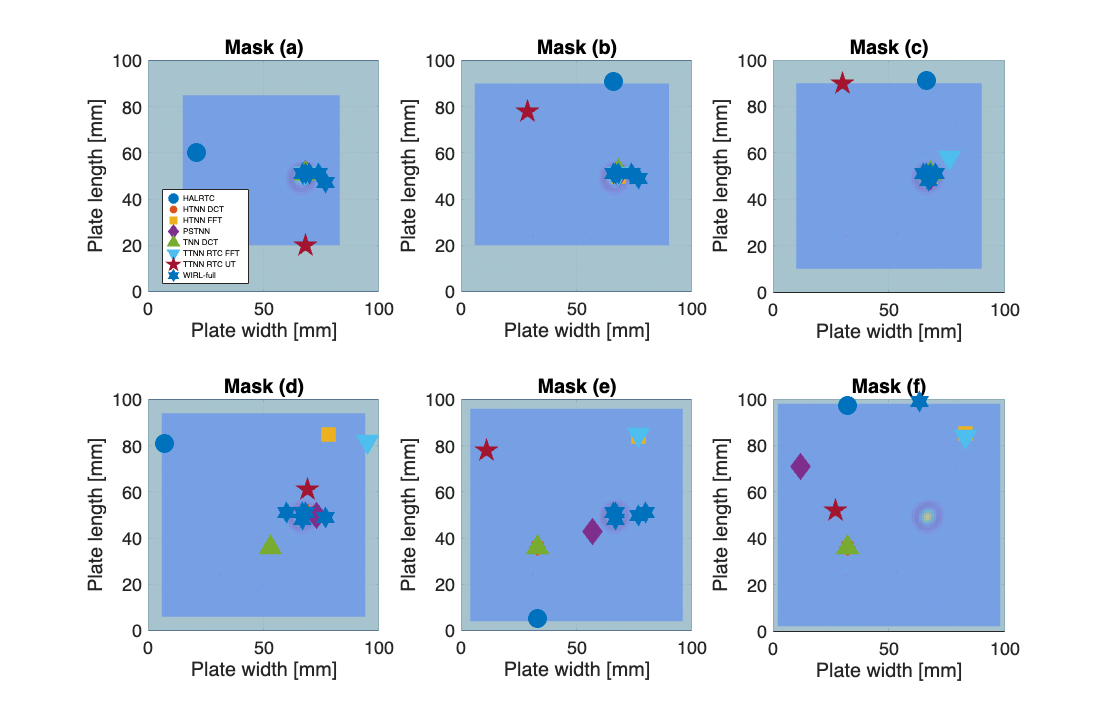


A = wave_data_dam(:,:,5);

centers = zeros(4,2,6);

A1B1 = floor([0.15,0.20;0.06,0.20;0.10,0.10;0.06,0.06;0.04,0.04;0.02,0.02]*100);
A3B3 = floor([0.83,0.85;0.90,0.90;0.90,0.90;0.94,0.94;0.96,0.96;0.98,0.98]*100);

for i = 1:6
    a1 = A1B1(i,1);
    b1 = A1B1(i,2);
    a3 = A3B3(i,1);
    b3 = A3B3(i,2);
    
    a2 = a1;
    b2 = b3;
    b4 = b1;
    a4 = a3;

    centers(1,1,i) = a1; centers(1,2,i) = b1;
    centers(2,1,i) = a2; centers(2,2,i) = b2;
    centers(3,1,i) = a3; centers(3,2,i) = b3;
    centers(4,1,i) = a4; centers(4,2,i) = b4;
end

% Assuming 'centers' is a 4x2x6 array and 'A' is a 100x100 matrix
% centers(i,:,indx) contains [x,y] coordinates of the i-th vertex for rectangle indx
% VERTICES ARE IN CLOCKWISE ORDER

% Load all results files
all_files = dir('./results/*_results.mat');

% Filter out secondary_results.mat
result_files = [];
for i = 1:length(all_files)
    [~, name, ~] = fileparts(all_files(i).name);
    if ~strcmp(name, 'secondary_results')
        result_files = [result_files; all_files(i)];
    end
end

% Define different marker shapes and colors for each file
marker_styles = {'o', '*', 's', 'd', '^', 'v', 'p', 'h', '+', 'x', '<', '>'};
marker_colors = lines(length(result_files));  % Generate distinct colors

% Initialize a cell array to store positions from each file separately
file_positions = cell(length(result_files), 6);
file_names = cell(length(result_files), 1);

% Load positions from all result files
for file_idx = 1:length(result_files)
    file_path = fullfile(result_files(file_idx).folder, result_files(file_idx).name);
    loaded_data = load(file_path);

    % Store the filename (without path and extension) for legend
    [~, name, ~] = fileparts(result_files(file_idx).name);

    % Custom naming for WIRL files
    if strcmp(name, 'primary_secondary_results')
        file_names{file_idx} = 'WIRL-full';
    elseif startsWith(name, 'primary_') && endsWith(name, '_results')
        % Extract the number between 'primary_' and '_results'
        % e.g., 'primary_1_results' -> 'WIRL-1'
        parts = split(name, '_');
        if length(parts) >= 2
            num_str = parts{2};
            file_names{file_idx} = ['WIRL-' num_str];
        else
            % Fallback if parsing fails
            file_names{file_idx} = strrep(name, '_', ' ');
        end
    else
        % Remove everything after the last underscore for other files
        last_underscore = find(name == '_', 1, 'last');
        if ~isempty(last_underscore)
            name = name(1:last_underscore-1);
        end
        file_names{file_idx} = strrep(name, '_', ' ');  % Replace remaining underscores with spaces
    end

    % Check if 'Positions' exists in the loaded data
    if isfield(loaded_data, 'Positions')
        positions = loaded_data.Positions;

        % Store positions from this file
        for indx = 1:6
            if ~isempty(positions{indx})
                file_positions{file_idx, indx} = positions{indx};
            end
        end
    end
end

% Create figure with 2x3 subplot layout
figure('Position', [100, 100, 1400, 900]);

% Define colors for rectangles and background (matching reference image)
rect_color = [0.53, 0.66, 0.87];    % Soft blue for inside rectangle
bg_color = [0.82, 0.88, 0.68];      % Pale greenish yellow for outside region
rect_alpha = 0.85;                   % Higher opacity for rectangle
bg_alpha = 0.85;                     % Higher opacity for background region
matrix_alpha = 0.3;                  % Lower transparency for matrix A overlay

% Define subplot labels
labels = {'(a)', '(b)', '(c)', '(d)', '(e)', '(f)'};

% Variables to store legend info (will be created only for first subplot)
legend_handles = [];
legend_labels = {};

% Loop through each rectangle
for indx = 6:-1:1
    % Create subplot
    subplot(2, 3, indx);
    hold on;

    % Extract individual vertices for current rectangle
    a1 = centers(1,1,indx); b1 = centers(1,2,indx);
    a2 = centers(2,1,indx); b2 = centers(2,2,indx);
    a3 = centers(3,1,indx); b3 = centers(3,2,indx);
    a4 = centers(4,1,indx); b4 = centers(4,2,indx);

    % Rectangle vertices (clockwise, closing the polygon)
    rect_x = [a1, a2, a3, a4, a1];
    rect_y = [b1, b2, b3, b4, b1];

    % Fill the entire square with background color FIRST
    fill([0, 100, 100, 0], [0, 0, 100, 100], ...
         bg_color, 'FaceAlpha', bg_alpha, 'EdgeColor', 'none');

    % Fill the rectangle on top
    fill(rect_x, rect_y, rect_color, 'FaceAlpha', rect_alpha, ...
         'EdgeColor', 'none');

    % Display background matrix A with transparency ON TOP
    h = imagesc([0 100], [0 100], A);
    set(h, 'AlphaData', matrix_alpha);  % Make matrix A transparent
    colormap(gca, 'parula');  % Using parula colormap as requested

    axis equal;
    axis([0 100 0 100]);
    set(gca, 'YDir', 'normal');

    % Plot positions from each file with different markers
    for file_idx = 1:length(result_files)
        if ~isempty(file_positions{file_idx, indx})
            pos = file_positions{file_idx, indx};

            % Get marker style (cycle through if more files than markers)
            marker_idx = mod(file_idx - 1, length(marker_styles)) + 1;

            % Plot with unique marker and color
            h_plot = plot(pos(:,2), pos(:,1), ...
                marker_styles{marker_idx}, ...
                'Color', marker_colors(file_idx, :), ...
                'MarkerSize', 8, ...
                'LineWidth', 1.5, ...
                'MarkerFaceColor', marker_colors(file_idx, :));

            % Store handle and label for legend (only for first subplot)
            if indx == 1
                legend_handles = [legend_handles, h_plot];
                legend_labels = [legend_labels, file_names{file_idx}];
            end
        end
    end

    % Add legend only for the first subplot
    if indx == 1 && ~isempty(legend_handles)
        lgd = legend(legend_handles, legend_labels, ...
            'Location', 'best', ...
            'FontSize', 4);
    end

    % Add labels and formatting
    xlabel('Plate width [mm]', 'FontSize', 11);
    ylabel('Plate length [mm]', 'FontSize', 11);
    title(sprintf('Mask %s', labels{indx}), 'FontSize', 11);

    % Make tick labels smaller
    set(gca, 'FontSize', 9);

    % Match the grid style from reference
    grid on;
    set(gca, 'GridAlpha', 0.15);  % Subtle grid
    box on;

    hold off;
end


% Adjust subplot spacing
set(gcf, 'Color', 'w');





% Load the .mat files
load('./results/primary_secondary_results.mat', 'Positions');
load('./results/secondary_results.mat', 'Positions_defect');


% Define mask labels
mask_labels = {'(a)', '(b)', '(c)', '(d)', '(e)', '(f)'};

% Initialize cell arrays to store table data
nCases = 6; % Number of cases

% Preallocate cell arrays for the tables
primaryTableData = cell(nCases, 1);
defectTableData = cell(nCases, 1);

% Process Positions_primary data
for i = 1:nCases
    positions = Positions{i};
    if ~isempty(positions)
        % Format as coordinate pairs: (x1, y1), (x2, y2), ...
        coordStrings = cell(size(positions, 1), 1);
        for j = 1:size(positions, 1)
            coordStrings{j} = sprintf('(%.2f, %.2f)', positions(j, 1), positions(j, 2));
        end
        primaryTableData{i} = strjoin(coordStrings, '; ');
    else
        primaryTableData{i} = 'No detections';
    end
end

% Process Positions_defect data
for i = 1:nCases
    positions = Positions_defect{i};
    if ~isempty(positions)
        % Format as coordinate pairs
        coordStrings = cell(size(positions, 1), 1);
        for j = 1:size(positions, 1)
            coordStrings{j} = sprintf('(%.2f, %.2f)', positions(j, 1), positions(j, 2));
        end
        defectTableData{i} = strjoin(coordStrings, '; ');
    else
        defectTableData{i} = 'No detections';
    end
end

% Create the tables using mask labels
% Table 1: Primary damage positions
primaryTable = table(mask_labels', primaryTableData, ...
    'VariableNames', {'Mask', 'Estimated_Primary_Source_Locations'});

% Table 2: Secondary defect positions
defectTable = table(mask_labels', defectTableData, ...
    'VariableNames', {'Mask', 'Locations_Secondary_Source_Locations'});

% Display the tables
disp('Table 1: Primary Damage Detection Results for WIMF (N_D = 4)');

Table 1: Primary Damage Detection Results for WIMF (N_D = 4)


disp(primaryTable);

     Mask                              Estimated_Primary_Source_Locations                        
    _______    __________________________________________________________________________________

    {'(a)'}    {'(51.00, 67.00); (51.00, 68.00); (51.00, 74.00); (47.00, 77.00); (51.00, 70.00)'}
    {'(b)'}    {'(51.00, 67.00); (51.00, 74.00); (51.00, 68.00); (49.00, 77.00); (51.00, 66.00)'}
    {'(c)'}    {'(51.00, 66.00); (48.00, 67.00); (51.00, 68.00); (51.00, 70.00); (51.00, 65.00)'}
    {'(d)'}    {'(51.00, 67.00); (48.00, 67.00); (49.00, 77.00); (51.00, 68.00); (51.00, 60.00)'}
    {'(e)'}    {'(51.00, 66.00); (50.00, 77.00); (48.00, 67.00); (51.00, 67.00); (51.00, 80.00)'}
    {'(f)'}    {'(99.00, 63.00); (99.00, 63.00)'                                                }




fprintf('\n\n');

disp('Table 2: Secondary Defect Detection Results for WIMF (N_D = 1)');

Table 2: Secondary Defect Detection Results for WIMF (N_D = 1)


disp(defectTable);

     Mask      Locations_Secondary_Source_Locations
    _______    ____________________________________

    {'(a)'}             {'(68.00, 37.00)'}         
    {'(b)'}             {'(67.00, 38.00)'}         
    {'(c)'}             {'(67.00, 37.00)'}         
    {'(d)'}             {'(71.00, 37.00)'}         
    {'(e)'}             {'(73.00, 31.00)'}         
    {'(f)'}             {'(30.00, 99.00)'}         




% Optional: Save tables to file
writetable(primaryTable, './results/primary_damage_table.csv');
writetable(defectTable, './results/secondary_defect_table.csv');

fprintf('\nTables saved to CSV files.\n');


Tables saved to CSV files.
